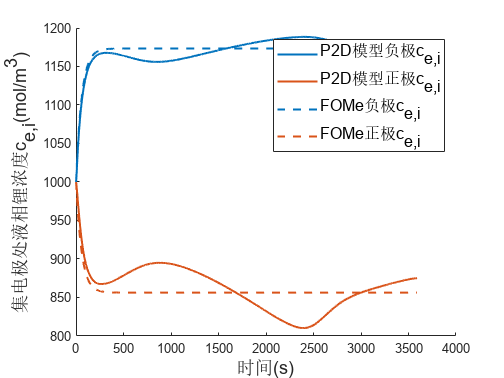

clc;
clear;
Dsn=3.9e-14;
Dsp=1e-13;

Rsn=12.5e-6;
Rsp=8e-6;

epssn=0.471;
epssp=0.297;

Ln=100e-6;
Ls=52e-6;
Lp=183e-6;

Lsum=Ln+Ls+Lp;

cs0neg=14870;
cs0pos=3900;

csmaxneg=26390;
csmaxpos=22860;

A=1;

F=96485.33289;

Qn=A*Ln*epssn*csmaxneg*F/3600;  %Ah
Qp=A*Lp*epssp*csmaxpos*F/3600;  %Ah

theta0n=cs0neg/csmaxneg;
theta0p=cs0pos/csmaxpos;

I=-17.5*[ones(3590,1)];
Jn=I*Rsn/3/epssn/F/A/Ln;
Jp=-I*Rsp/3/epssp/F/A/Lp;
t=1:length(I);

load cen_load.txt;
load cep_load.txt;
p2d_cen=cen_load(:,2);
p2d_cep=cep_load(:,2);
[fom_cen,fom_cep]=sp_electrolyte(I);
fom_cen=fom_cen';
fom_cep=fom_cep';

figure(1);
clf;
hold on;
plot(p2d_cen,Color="#0072BD",LineWidth=1.5);
plot(p2d_cep,LineWidth=1.5);
plot(fom_cen,'--',Color="#0072BD",LineWidth=1.5);
plot(fom_cep,'--',Color="#D95319",LineWidth=1.5);
legend('P2D模型负极c_{e,i}','P2D模型正极c_{e,i}','FOMe负极c_{e,i}','FOMe正极c_{e,i}',fontsize=12);
xlabel('时间(s)','fontsize',14);
ylabel('集电极处液相锂浓度c_{e,i}(mol/m^3)','fontsize',14);

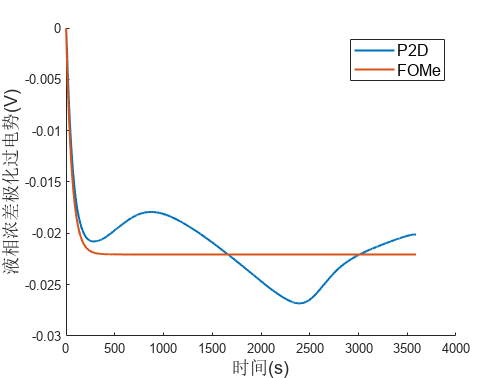

% error(1,1)=RMSE(fom_cen,p2d_cen);
% error(1,2)=RMSE(fom_cep,p2d_cep);
% error(2,1)=MAPE(fom_cen,p2d_cen);
% error(2,2)=MAPE(fom_cep,p2d_cep);

t_plus=0.363;
Rg=8.314;
T=298.15;
Rohm=1.2e-3;

p2d_e=(1+t_plus)*2*Rg*T/F*log(p2d_cep./p2d_cen);
fom_e=(1+t_plus)*2*Rg*T/F*log(fom_cep./fom_cen);

figure(2);
clf;
hold on;
plot(p2d_e,LineWidth=1.5);
plot(fom_e,LineWidth=1.5);
legend('P2D','FOMe',fontsize=12);
xlabel('时间(s)','fontsize',14);
ylabel('液相浓差极化过电势(V)','fontsize',14);

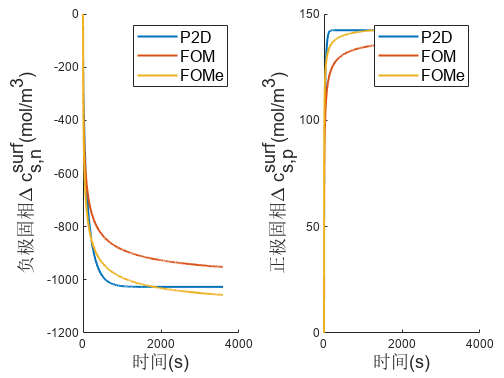

% RMSE(fom_e,p2d_e)*1000
% setting = optimoptions('particleswarm','SwarmSize',500,'Display','iter','MaxIterations',500);
% [x,evalu] = particleswarm(@findab,2,[0,0],[1,1],setting)

load dcsen_load.txt;
load dcsep_load.txt;
p2d_dcsen=dcsen_load(:,2);
p2d_dcsep=dcsep_load(:,2);
fom_dcsen=fom(Rsn,Dsn,Jn);
fom_dcsep=fom(Rsp,Dsp,Jp);
fome_dcsen=fomn(Rsn,Dsn,Jn);
fome_dcsep=fomp(Rsp,Dsp,Jp);

figure(3);
clf;
tiledlayout(1,2,'TileSpacing','Compact','Padding','Compact');
nexttile
hold on;
plot(p2d_dcsen,LineWidth=1.5);
plot(fom_dcsen,LineWidth=1.5);
plot(fome_dcsen,LineWidth=1.5);
legend('P2D','FOM','FOMe',fontsize=12);
xlabel('时间(s)','fontsize',14);
ylabel('负极固相\Delta c_{s,n}^{surf}(mol/m^3)','fontsize',14);
nexttile
hold on;
plot(p2d_dcsep,LineWidth=1.5);
plot(fom_dcsep,LineWidth=1.5);
plot(fome_dcsep,LineWidth=1.5);
legend('P2D','FOM','FOMe',fontsize=12);
xlabel('时间(s)','fontsize',14);
ylabel('正极固相\Delta c_{s,p}^{surf}(mol/m^3)','fontsize',14);

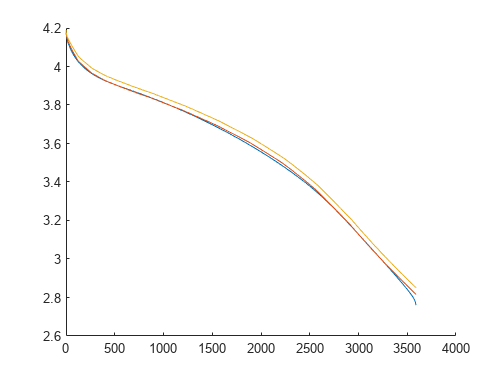

% error(1,1)=RMSE(p2d_dcsep,fom_dcsep);
% error(1,2)=RMSE(p2d_dcsen,fom_dcsen);
% error(2,1)=RMSE(p2d_dcsep,fome_dcsep);
% error(2,2)=RMSE(p2d_dcsen,fome_dcsen);

soc_ave_p=theta0p+cumsum(-I)/3600/Qp;
soc_ave_n=theta0n+cumsum(I)/3600/Qn;
fome_surfp=soc_ave_p+fome_dcsep/csmaxpos;
fome_surfn=soc_ave_n+fome_dcsen/csmaxneg;

fom_surfp=soc_ave_p+fom_dcsep/csmaxpos;
fom_surfn=soc_ave_n+fom_dcsen/csmaxneg;

load v_load.txt;
V_P2D=v_load(:,2);
V_fome=Eeqp(fome_surfp)-Eeqn(fome_surfn)+Rohm*I+fom_e;
V_fom=Eeqp(fom_surfp)-Eeqn(fom_surfn)+Rohm*I;

figure(4);
clf;
hold on;
plot(V_P2D);
plot(V_fome);
plot(V_fom);

error(1,1)=RMSE(V_P2D,V_fome)*1000;
error(1,2)=RMSE(V_P2D,V_fom)*1000;
error(2,1)=MAPE(V_P2D,V_fome);
error(2,2)=MAPE(V_P2D,V_fom);